# Palabra más repetida

clear; clc; warning off;
[x,t]=xlsread('DBTweets.xlsx');
t=t(2:end); tc=string(t);
tc=unique(tc); tc=eraseURLs(tc);
CD=tokenizedDocument(tc);
CD=normalizeWords(CD,"Style","lemma");
CD=erasePunctuation(CD);


## Parte 1

allwords=CD(1).Vocabulary;
for i=2:1:length(CD)
    allwords=cat(2,allwords,CD(i).Vocabulary);        
end
[C,ia,ic]=unique(allwords);
a=accumarray(ic,1); id=find(a==max(a));
fprintf('La palabra más repetida es "%s" y se repite %d veces \n',C(id),max(a));

La palabra más repetida es "de" y se repite 667 veces 


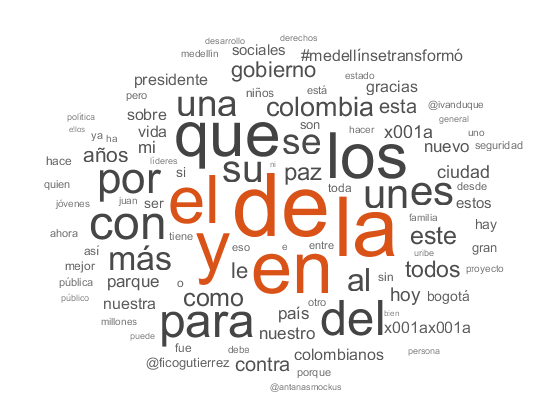

wordcloud(allwords);

cn=wordCloudCounts(allwords);
head(cn)

ans = 8×2 table
    Word     Count
    _____    _____

    "de"      667 
    "la"      605 
    "en"      493 
    "y"       450 
    "el"      409 
    "que"     376 
    "los"     375 
    "del"     235 


## Parte 2

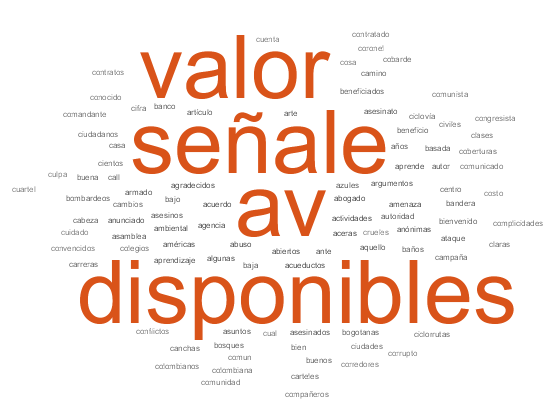

CB=bagOfWords(CD);
aw=CB.Vocabulary;
wordcloud(aw);

## Parte 3

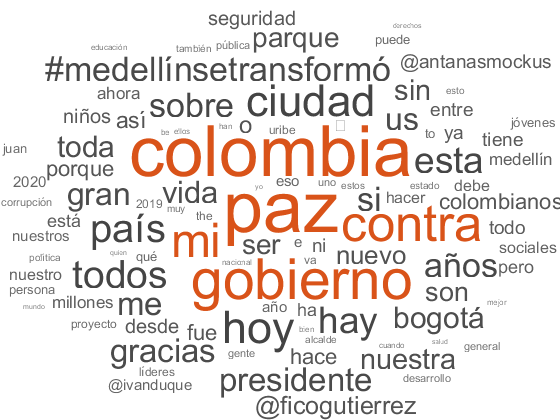

ConWor=["de" "la" "en" "y" "el" "a" "que" "los" "del" "para" "con" "no" "por" "un" "es" "se" "una"...
    "más" "al" "su" "lo" "este" "le" "sus" "x001a" "como" "x001ax001a"];
CB=removeWords(CB,ConWor);
wordcloud(CB);